## Example #1

### Random tetrahedron from the 3D space

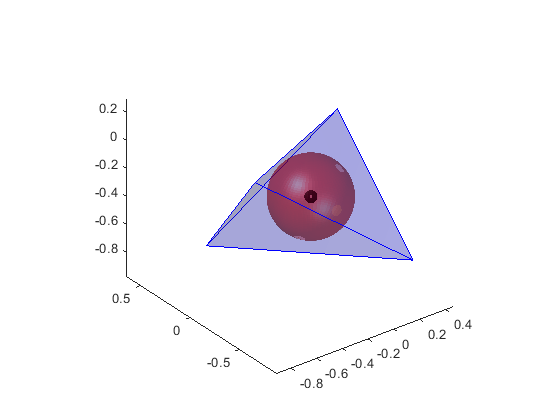

V = 2*(rand(3,4)-0.5);
tetrahedron_insphere(V(:,1),V(:,2),V(:,3),V(:,4));

## Example #2

### Regular tetrahedron in the unit ball

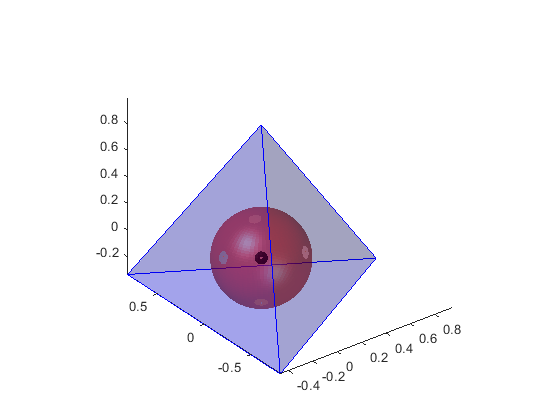

I = 	1.0e+-16 *

   -0.9615
         0
    0.5949


r = 0.3333

A = [0 0 1]';
B = [2*sqrt(2)/3 0 -1/3]';
C = [-sqrt(2)/3 sqrt(6)/3 -1/3]';
D = [-sqrt(2)/3 -sqrt(6)/3 -1/3]';
[I,r] = tetrahedron_insphere(A,B,C,D,true) % expected : I = [0 0 0]; r = 1/3;

## Example #3

### Flat / degenerated tetrahedron

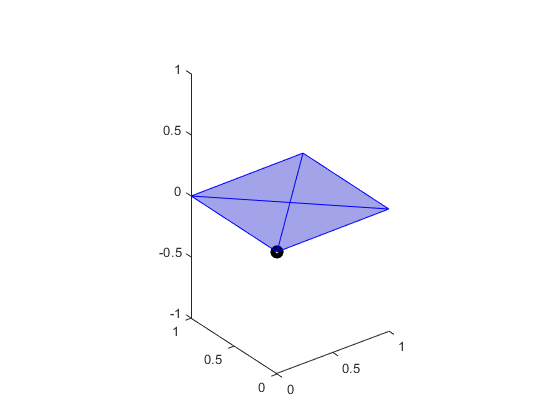

A = [0 0 0]';
B = [1 0 0]';
C = [0 1 0]';
D = [1 1 0]';
[I,r,rc] = tetrahedron_insphere(A,B,C,D,true);

rc % expected : rc = 0

rc = logical
   0
